# Análise de Fourier de sinais de aúdio - 1860

## Boas práticas

clear all;
close all;
clc;

## leitura de arquivo .wav - audioread

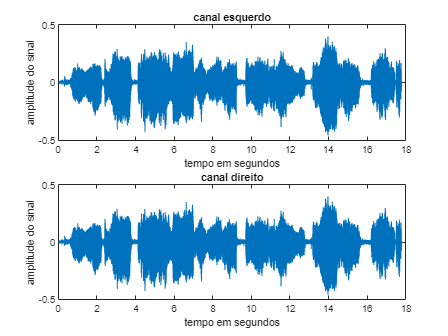

% audioread Read audio files
%    [Y, FS] = audioread(FILENAME) reads an audio file specified by the
%    character vector or string scalar FILENAME, returning the sampled data
%    in Y and the sample rate FS, in Hertz.
[Y , FS] = audioread("audio1.wav");
%%%% criando vetor tempo
TS = 1/FS;                                  % TEMPO ENTRE AMOSRTRAS
Npontos = length(Y);
Vfinal = (Npontos-1)*TS;                    % VALOR FINAL NO TEMPO
tempo = linspace(0,Vfinal, Npontos);        % numero de pontos do vetor Y

figure(1)
subplot(2,1,1)
plot(tempo, Y(:,1))
xlabel('tempo em segundos')
ylabel('amplitude do sinal')
title('canal esquerdo')
subplot(2,1,2)
plot(tempo, Y(:,2))
xlabel('tempo em segundos')
ylabel('amplitude do sinal')
title('canal direito')

## ouvir um arquivo .wav

% audiowrite write audio files
%    audiowrite(FILENAME,Y,FS)  writes data Y to an audio
%    file specified by the file name FILENAME, with a sample rate
%    of FS Hz.
%    Stereo data should be specified as a matrix with two columns.
%    Multi-channel data should be specified as a matrix of N columns.

% sound Play vector as sound.
%    sound(Y,FS) sends the signal in vector Y (with sample frequency
%    FS) out to the speaker on platforms that support sound. Values in
%    Y are assumed to be in the range -1.0 <= y <= 1.0. Values outside
%    that range are clipped.  Stereo sounds are played, on platforms
%    that support it, when Y is an N-by-2 matrix.

sound(Y, FS)

## aplicar a FFT - Fast Fourier Transform

% fft Discrete Fourier transform.
%    fft(X) is the discrete Fourier transform (DFT) of vector X.  For
%    matrices, the fft operation is applied to each column. For N-D
%    arrays, the fft operation operates on the first non-singleton
%    dimension.

FY = fftshift(fft(Y));

## Visualizar a FFT e interpretar

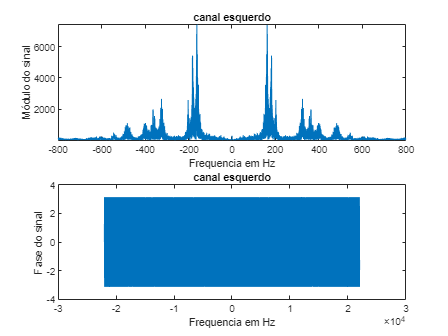

%%%%% Criar a variável frequência
frequencia = linspace(-FS/2,FS/2,Npontos);

figure(2)

subplot(2,1,1)
plot(frequencia, abs(FY(:,1)))
xlabel('Frequencia em Hz')
ylabel('Módulo do sinal')
title('canal esquerdo')

subplot(2,1,2)
plot(frequencia, angle(FY(:,1)))
xlabel('Frequencia em Hz')
ylabel('Fase do sinal')
title('canal esquerdo')

subplot(2,1,1)
xlim([-800 800])
ylim([24 7400])

## Conclusão

display('a partir da análise do gráfico de frequência em relação ao módulo do sinal percebe-se que não é necessário um arquivo de 44100 Hz e que um arquivo com 500Hz descreveria o aúdio fácilmente')

a partir da análise do gráfico de frequência em relação ao módulo do sinal percebe-se que não é necessário um arquivo de 44100 Hz e que um arquivo com 500Hz descreveria o aúdio fácilmente
